**INITIAL CLEARANCE OF THE WORKSPACE**

clear all;

**FILE IMPORT AND UNPACK**

% % load camera parameters
% LoadCameraParameters('./camera_parameters_lab.mat');
% 
% % read the image of the checkerboard
% image = imread('.\test images\checkerboard_lab_rgb.png');

camera = Camera3D('./camera_parameters_lab.mat');

ans =   cameraIntrinsics with properties:

             FocalLength: [925.9654 925.9056]
          PrincipalPoint: [641.6597 380.0837]
               ImageSize: [720 1280]
        RadialDistortion: [0.1506 -0.2320]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3×3 double]


Intel RealSense D435



% define the physical dimensions of a checkerboard square in millimeters.
edgeLength = 30;

% construct the 42 checkerboard points from points 1 and 6 in the rcs
% boardOriginRCS = [282.8  69.4]; % point 1 in rcs
% boardCornerRCS = [280.0 -81.9]; % point 6 in rcs
boardOriginRCS = [310  76.35]; % point 1 in rcs
boardCornerRCS = [311.93 -74.62]; % point 6 in rcs

[image, ~] = camera.snapshot();

transform = TransformPCStoCCS(image, camera.parameters, edgeLength);

 -356.9580  128.3046

 -266.6189  247.9217

Score: 100.6 %


diff =    -0.0000   -0.0083
   -0.0000   -0.0098
   -0.0000   -0.0114
   -0.0000   -0.0129
   -0.0000   -0.0145
   -0.0000   -0.0160
   -0.0000   -0.0071
   -0.0000   -0.0087
   -0.0000   -0.0102
   -0.0000   -0.0118



transform.extendToRCS(boardOriginRCS, boardCornerRCS);

% define a set of pixel coordinates for testing
testPointsPCS = [camera.parameters.PrincipalPoint; 
    camera.parameters.PrincipalPoint + 150;
    0 0];

% apply full transformation on the testing set
testPointsRCS = transform.apply(testPointsPCS)

**VISUALIZATION**

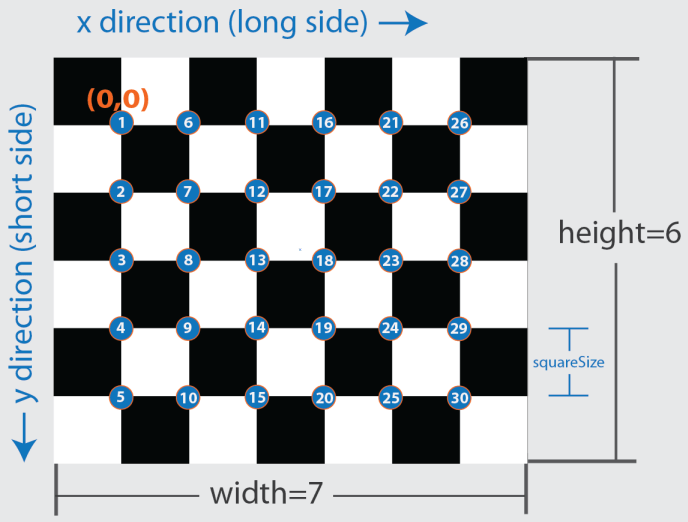

% display the image and plot the detected corners and axes
transform.show(image);